# Example: Creating a Basket Cell

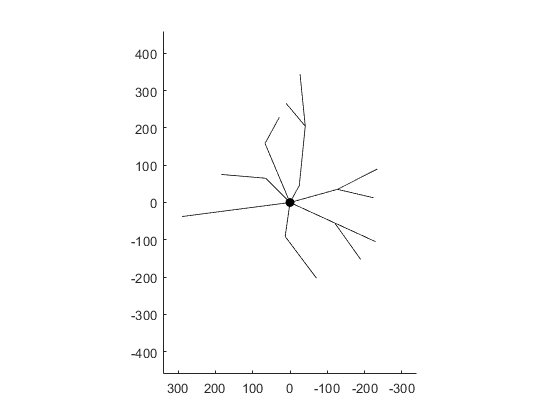

cell = ELFENN.Cell('cell');

soma = ELFENN.Section('soma',...
    'radius', 12,...
    'sectionGeometry', 'S',...
    'sectionLength', 24,...
    'nSeg' , 1);


%%Branch 1
axon_main = ELFENN.Section('axon-main-1', ...
    'radius', 1,...
    'nSeg', 3,...
    'sectionLength', 40);

cell.connectsection(soma, axon_main, [0,0,-0.5]);

axon_main_copy = ELFENN.Section('axon-main-2', ...
    'radius', 1,...
    'nSeg', 9,...
    'sectionLength', 160);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-2', [0,0,0.4]);
axon_main = axon_main_copy;

axon_main_copy = ELFENN.Section('axon-main-3', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 80);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-3', [0,0,1.2]);

axon_main_copy = ELFENN.Section('axon-main-4', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 140);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-4', [0,0,0.6]);

%% Branch 2

axon_main = ELFENN.Section('axon-main-5', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 120);

cell.connectsection(soma, axon_main, [0,0,-1.3]);

axon_main_copy = ELFENN.Section('axon-main-6', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 100);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-6', [0,0,-0.5]);

axon_main_copy = ELFENN.Section('axon-main-7', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 120);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-7', [0,0,0.2]);

%% Branch 3


axon_main = ELFENN.Section('axon-main-8', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 120);

cell.connectsection(soma, axon_main, [0,0,-2]);

axon_main_copy = ELFENN.Section('axon-main-9', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 120);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-9', [0,0,0]);

axon_main_copy = ELFENN.Section('axon-main-10', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 120);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-10', [0,0,-pi/6]);

%% Branch 4

axon_main = ELFENN.Section('axon-main-11', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 80);

cell.connectsection(soma, axon_main, [0,0,3]);

axon_main_copy = ELFENN.Section('axon-main-12', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 140);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-12', [0,0,pi/4]);

%% Branch 5


axon_main = ELFENN.Section('axon-main-13', ...
    'radius', 1,...
    'nSeg', 15,...
    'sectionLength', 280);

cell.connectsection(soma, axon_main, [0,0,1.7]);

%% Branch 6

axon_main = ELFENN.Section('axon-main-14', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 80);

cell.connectsection(soma, axon_main, [0,0,pi/4]);

axon_main_copy = ELFENN.Section('axon-main-15', ...
    'radius', 1,...
    'nSeg', 7,...
    'sectionLength', 120);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-15', [0,0,0.7]);

%% Branch 7


axon_main = ELFENN.Section('axon-main-16', ...
    'radius', 1,...
    'nSeg',9,...
    'sectionLength', 160);

cell.connectsection(soma, axon_main, [0,0,0.4]);

axon_main_copy = ELFENN.Section('axon-main-17', ...
    'radius', 1,...
    'nSeg', 5,...
    'sectionLength', 80);

cell.connectsection(axon_main, axon_main_copy);
cell.rotatechunk('axon-main-17', [0,0,-0.9]);

cell.rotateoffsoma('soma');

figure;
hold all
plotcell(cell);
daspect([1,1,1])
view([-90, 90])
ylim([-340,340]);
xlim([-460,460]);